#### METODE DE LES POTENCIES (MOD MAX)

A = [1 0 -1; 1 2 1; 2 2 3];

x0 = [1 1 1]';
tol = 1e-6;

x = x0;
for k = 1:200
    x_pre = x;
    zk = A*x;
    m = norm(zk);
    x = (zk/m);
    
    if (norm(x - x_pre, 'inf') < tol) 
        k, x, m
        break;
    end
end

k = 30

x =    -0.4082
    0.4082
    0.8165


m = 3.0000

#### METODE DE LES POTENCIES (MOD MIN)

clear vars
A = [1 0 -1; 1 2 1; 2 2 3];

x0 = [1 -1 1]';
tol = 1e-10;

invA = inv(A);

x = x0;
for k = 1:100
    x_pre = x;
    zk = invA*x;
    m = norm(zk, 'inf');
    x = (zk/m);
    
    if (norm(x - x_pre, 'inf') < tol) 
        k, x, m
        break;
    end
end

k = 22

x =     1.0000
   -1.0000
    0.0000


m = 1.0000

#### TESTING ENCAPSULADO EN FUNCIONES

A = -[1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
x0 = [1 -1 -1 1]';

% Minimo
[vap,vep,it,residu] = potencia_inversa(A,x0,50,eps);
vap,vep,it,residu

vap = -0.0122

vep =     1.0000
   -0.2257
    0.2501
   -0.0090


it = 8

residu = 1.1102e-16

% Maximo
[vap,vep,it,residu] = potencia(A,x0,50,eps);
vap,vep,it,residu

vap = -19.1820

vep =    -0.1719
   -1.0000
   -0.9875
   -0.7752


it = 50

residu = 2

#### QUOCIENT DE RAYLEIGH

% QuoRay
A = -[1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
x0 = [1 0 0 1]';

[vap,vep,it,residu] = potQuoRay(A,x0,50,eps);
vap,vep,it,residu

vap = -0.0122

vep =     2.0215
   -0.4562
    0.5057
   -0.0183


it = 8

residu = 1.1102e-16

#### QR

A = [1 0 -1; 1 2 1; 2 2 3];

A1 = A;

it = 0;
while it < 200 && norm(tril(A1,-1),'inf') > eps
    [Q, R] = qr(A1);
    A1 = R * Q;
    it = it + 1;
end

it, A1

it = 105

A1 =     3.0000    3.1305   -0.7303
   -0.0000    2.0000   -0.8165
   -0.0000    0.0000    1.0000


#### SINGULAR VALUE DECOMPOSITION

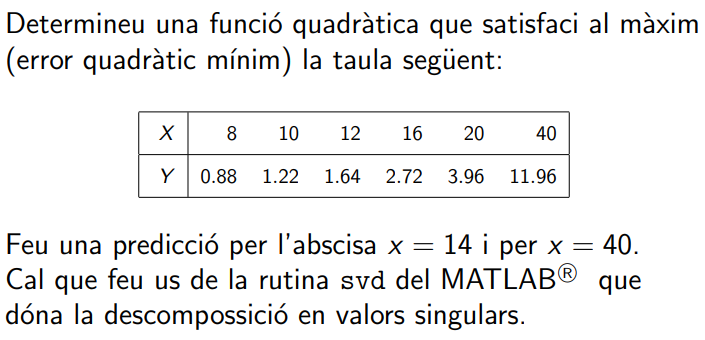

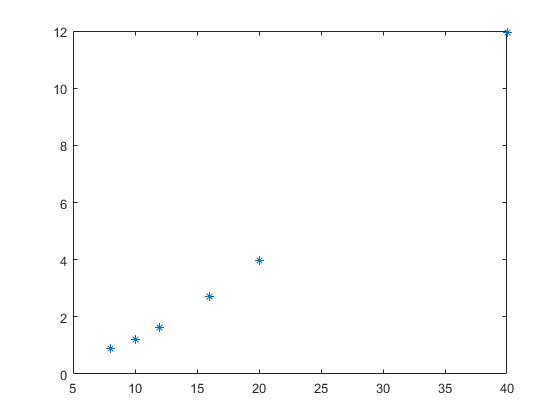

x = [8 10 12 16 20 40];
y = [0.88 1.22 1.64 2.72 3.96 11.96];

A = [(x.^2)', x', ones(size(x'))];
plot(x,y,'*');

coeff = A\y'

coeff =     0.0045
    0.1307
   -0.5166


[U,S,V] = svd(A)

U =    -0.0382    0.3418    0.6661    0.1526    0.3314   -0.5522
   -0.0597    0.3952    0.3788   -0.0713    0.2014    0.8069
   -0.0859    0.4364    0.1253   -0.4958   -0.7213   -0.1427
   -0.1526    0.4819   -0.2804    0.7692   -0.2717    0.0201
   -0.2383    0.4784   -0.5512   -0.3661    0.5036   -0.1512
   -0.9526   -0.2747    0.1211    0.0114   -0.0434    0.0191


S = 	1.0e+03 *

    1.6801         0         0
         0    0.0183         0
         0         0    0.0005
         0         0         0
         0         0         0
         0         0         0


V =    -0.9996   -0.0281    0.0020
   -0.0281    0.9944   -0.1015
   -0.0009    0.1015    0.9948


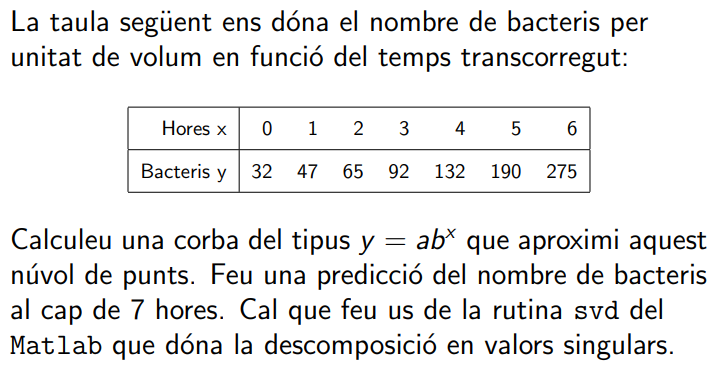

x = [0 1 2 3 4 5 6];
y = [32 47 65 92 132 190 275];

% y = ab^x  ===  ln y = ln a + x * ln b
b = log(y');
A = [x', ones(size(x'))];

coef = pinv(A)*b

coef =     0.3555
    3.4703


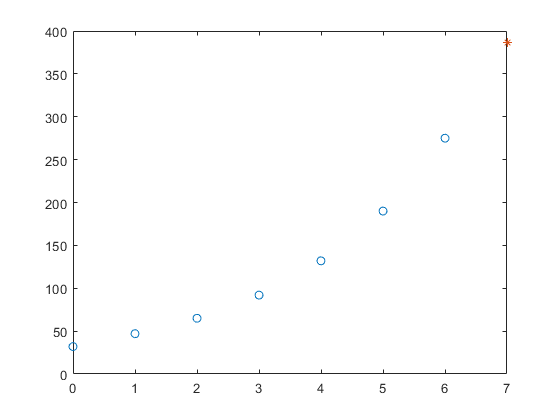

z = fix(exp(polyval(coef,7)));
plot(x,y,'o',7,z,'*')